# Atividade 6 - Análise discreta 

## Boas práticas

clear;                  %%% limpando todas as variáveis
close all;              %%% fechando todas as figuras
clc;                    %%% limpando a tela

## Abrindo os arquivos dos sinais

[y_Guitarra, fs_Guitarra] = audioread("2 - Fourier_Vogais_Guitarra_limpa.wav"); 
[y_Gaita,    fs_Gaita]    = audioread("2 - Fourier_Vogais_Gaita_Blues.wav");

%%% Ouvindo os sinais 
% sound(y_Guitarra, fs_Guitarra) -> estéreo
% sound(y_Gaita, fs_Gaita)       -> mono

## Exercício 1

%%% Valores das frequências
fs_Gaita, fs_Guitarra

fs_Gaita = 44100

fs_Guitarra = 44100

### Guitarra

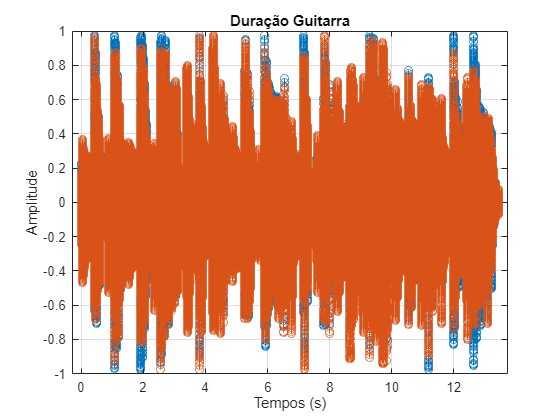

T_guitarra = 1/fs_Guitarra;                    %%% Período de amostragem do sinal
N_Guitarra = length(y_Guitarra);               %%% Número total de amostras do sinal
D_guitarra = (N_Guitarra - 1)*T_guitarra;      %%% Duração total do sinal em segundos (corrige o erro)
t_Guitarra = 0:T_guitarra:D_guitarra;          %%% Vetor de tempo correspondente ao sinal

%% Plota o sinal discretizado no tempo usando stem
stem(t_Guitarra, y_Guitarra);   
title('Duração Guitarra');
xlabel('Tempos (s)');
ylabel('Amplitude');
grid;

### Gaita

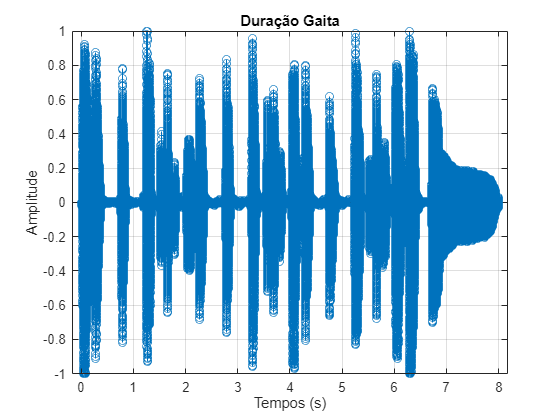

T_gaita = 1/fs_Gaita;                %%% Calcula o período de amostragem (tempo entre amostras) da gaita
N_Gaita = length(y_Gaita);           %%% Obtém o número total de amostras do sinal da gaita
D_gaita = (N_Gaita - 1)*T_gaita;     %%% Calcula a real duração total do sinal da gaita em segundos
t_Gaita = 0:T_gaita:D_gaita;         %%% Cria o vetor de tempo correspondente às amostras do sinal da gaita

%%% Plota o sinal discretizado no tempo usando stem
stem(t_Gaita, y_Gaita);
title('Duração Gaita');
xlabel('Tempos (s)');
ylabel('Amplitude');
grid;

## Exercício 2

### Guitarra

max_Guitarra = max(y_Guitarra)    %%% Encontra o valor máximo do sinal da guitarra

max_Guitarra =     0.9750    0.9750


min_Guitarra = min(y_Guitarra)    %%% Encontra o valor mínimo do sinal da guitarra

min_Guitarra =    -0.9750   -0.9750


### Gaita

max_Gaita    = max(y_Gaita)       %%% Encontra o valor máximo do sinal da gaita

max_Gaita = 1.0000

min_Gaita    = min(y_Gaita)       %%% Encontra o valor mínimo do sinal da gaita

min_Gaita = -1

## Exercício 3

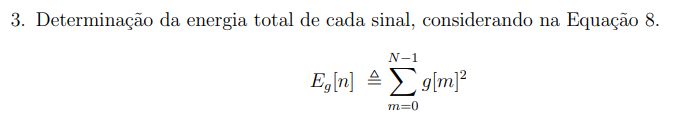

### Guitarra

Eg_guitarra = 0;                                                 %%% Zera acumulador de energia
primeira_coluna_Guitarra = y_Guitarra(:,1);                      %%% Usa canal 1 do estéreo

for a = 1 : N_Guitarra                                           %%% Para cada amostra da guitarra
    Eg_guitarra = Eg_guitarra + primeira_coluna_Guitarra(a)^2;   %%% Soma quadrado da amostra
end                                                              %%% Fim do laço

Eg_guitarra        

Eg_guitarra = 2.0042e+04

### Gaita

Eg_gaita = 0;                                %%% Zera acumulador de energia

for k = 1 : N_Gaita                          %%% Para cada amostra da gaita
    Eg_gaita = Eg_gaita + y_Gaita(k)^2;      %%% Soma quadrado da amostra
end                                          %%% Fim do laço

Eg_gaita                                     %%% Exibe energia total da gaita

Eg_gaita = 7.9022e+03

## Exercício 4

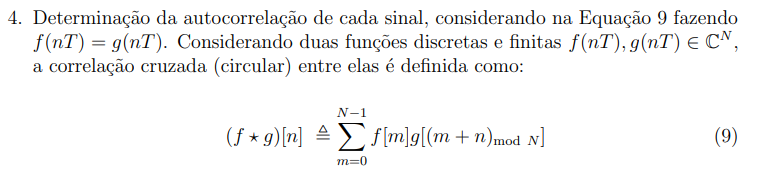

### Guitarra

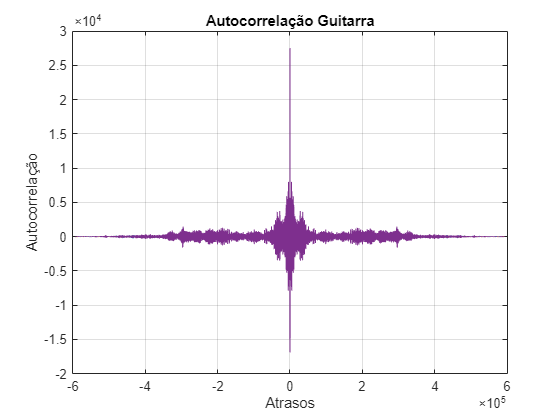

%%% Autocorrelação do sinal da guitarra
[autocor_guitarra, atraso_guitarra] = xcorr(y_Guitarra);

%%% Plota autocorrelação da guitarra
figure;                                                    
plot(atraso_guitarra, autocor_guitarra);                   
xlabel('Atrasos');                                         
ylabel('Autocorrelação');                                  
title('Autocorrelação Guitarra');                          
grid;                                                      

### Gaita

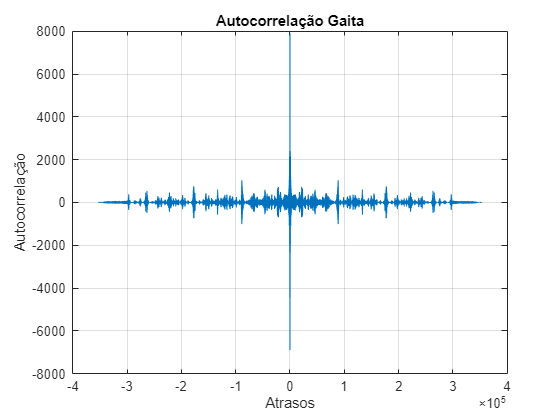

%%% Autocorrelação do sinal da gaita
[autocor_gaita, atraso_gaita]       = xcorr(y_Gaita);                                               

%%% Plota autocorrelação da gaita
figure;                                                   
plot(atraso_gaita, autocor_gaita);                         
xlabel('Atrasos');                                         
ylabel('Autocorrelação');                                  
title('Autocorrelação Gaita');                             
grid;               

**OBS:** Não foi possível fazer a implementação usando a correlação cruzada circular uma vez que ela não conseguia finalizar seu tempo de execução. Sendo assim, para fazer a correlação, foi testada e usada a correlação linear

## Exercício 5

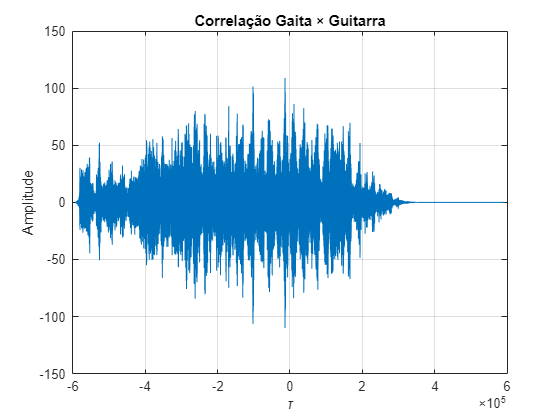

%%% Correlação cruzada entre gaita e guitarra
[r, atr] = xcorr(y_Gaita, primeira_coluna_Guitarra);

%%% Plota o resultado
plot(atr, r);                                         
xlabel('\tau');                                       
ylabel('Amplitude');                                  
title('Correlação Gaita × Guitarra');                 
grid;                                                 

%%% Som da correlação
%%% sound(r, fs_Gaita);                                   

A correlação cruzada entre os sinais da gaita e da guitarra revela os instantes em que eles apresentam maior semelhança: picos elevados em certos atrasos indicam alinhamentos fortes de padrões sonoros em cada instrumento. Ao ouvir o sinal de correlação, percebe-se um som que enfatiza esses momentos de coincidência — como um “eco” ou reforço das frequências compartilhadas — permitindo concluir que, apesar das diferenças tímbricas, existem componentes harmônicos em comum que se sobressaem quando os dois sinais são deslocados corretamente.

## Exercício 6

## 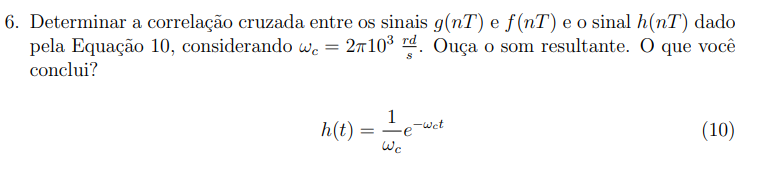

### Sinal h(t)

wc           = 2*pi*1e3;                            %%% Define ωc = 2π·10³ rad/s
h_gaita      = (1/wc) * exp(-wc * t_Gaita);         %%% Calcula h(t) no vetor de tempo da gaita

### Guitarra

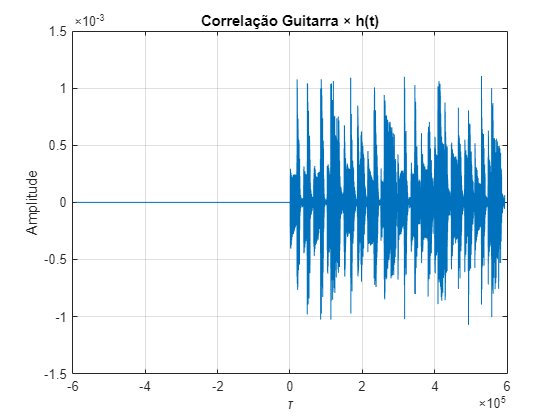

%%% Sinal h(t) para a guitarra
h_guit       = (1/wc) * exp(-wc * t_Guitarra);      %%% Calcula h(t) no vetor de tempo da guitarra

%%% Correlação entre h(t) e o sinal da guitarra
[r_h_guit, atr_guit] = xcorr(primeira_coluna_Guitarra, h_guit);

%%% Plot correlação vs atraso
figure;                                             
plot(atr_guit, r_h_guit);                                       
xlabel('\tau'), ylabel('Amplitude');                
title('Correlação Guitarra × h(t)');
grid;      

### Gaita

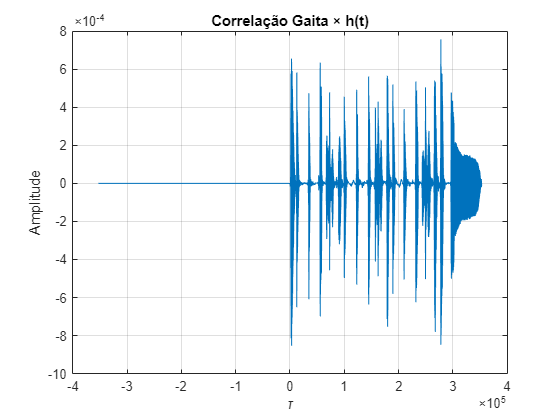

%%% Correlação entre h(t) e o sinal da gaita
[r_h_gait, atr_gaita] = xcorr(y_Gaita, h_gaita);

%%% Plot correlação vs atraso
figure;                                             
plot(atr_gaita, r_h_gait);                          
xlabel('\tau'); 
ylabel('Amplitude');                
title('Correlação Gaita × h(t)');
grid;             

### Sons resultantes

sound(1000 * r_h_guit/1.5, fs_Guitarra);            %%% Reproduz correlação guitarra
sound(10000 * r_h_gait/8,  fs_Gaita);               %%% Reproduz correlação gaita

De forma semelhante ao exercício anterior, ao ouvir os sinais gerados pelas correlações cruzadas, estamos percebendo as semelhanças entre os sinais da Guitarra e da Gaita, bem como entre os sinais de cada um e a função de resposta ao impulso h(t).